# Задание 1

y_0_arr = [ 1 1 1 0.05 0.05 0 ];
dot_y_0_arr = [ 0 0 0 0 0 0.1 ];
lambda_1_arr = [ -4.5 -3.7+5i 29i 0.7+5i 4.5 -2.8 ];
lambda_2_arr = [ -5.5 -3.7-5i -29i 0.7-5i 5.5 2.8 ];

Выведем общую формулу для вычисления $a_0, a_1$:

Характеристическое уравнение: $\lambda^2+a_1\lambda+a_0=0$

Получим систему:


$$\begin{cases}
a_1=-\lambda_1-\lambda_2\\
a_0=\lambda_1\cdot\lambda_2
\end{cases}$$


Вычислим коэффициеты:

a_0_arr = zeros(1, 6);
a_1_arr = zeros(1, 6);

for k = 1:6
    a_1_arr(k) = - lambda_1_arr(k) - lambda_2_arr(k);
    a_0_arr(k) = lambda_1_arr(k) * lambda_2_arr(k);
end
fprintf('№  a_1\t\t a_0\n');

№  a_1		 a_0


for k = 1:6
    fprintf('%1i %7.3f\t%7.3f\n', ...
        k, a_1_arr(k), a_0_arr(k));
end

1  10.000	 24.750
2   7.400	 38.690
3   0.000	841.000
4  -1.400	 25.490
5 -10.000	 24.750
6   0.000	 -7.840


Получаем:

`№  a_1		 a_0`

`1  10.000	 24.750`

`2   7.400	 38.690`

`3   0.000	841.000`

`4  -1.400	 25.490`

`5 -10.000	 24.750`

`6   0.000	 -7.840`

`Перепишем наше ДУ в более удобном виде для построения схемы:`


$$p^2y+a_1py+a_0y=a_0u\Rightarrow
y=-\frac{1}{p}(a_1y+\frac{1}{p}a_0(y-u))
$$


Выразим начальные условия для интеграторов:

1. $y(0)=\frac{1}{p}(-a_1y-\frac{1}{p}a_0(y-u))\Rightarrow $для второго интегратора начальное условие $y(0)
$.

2. $py=(-a_1y-\frac{1}{p}a_0(y-u))=0\Rightarrow\frac{1}{p}a_0(y-u)=-py-a_1y\Rightarrow$для первого интегратора начальное условие $-\dot{y}(0)-a_1y(0)$.

Найдём аналитическое выражение для свободной составляющей движения системы $y_{\text{св}}(t)$ для каждого варианта:

1. $\begin{cases}
y_{св}(t)=C_1e^{-4.5t}+C_2e^{-5.5t}\\
y(0)=1 \\
\dot{y}(0)=0
\end{cases}\Rightarrow
\begin{cases}
C_1+C_2=1\\
 -4.5C_1-5.5C_2=0
\end{cases}\Rightarrow
\begin{cases}
C_1=5.5\\
C_2=-4.5
\end{cases}\\
y_{св}(t)=5.5e^{-4.5t}-4.5e^{-5.5t}$

2. $\[
\begin{cases}
y_{\text{св}}(t)=e^{-3.7t}(C_1\sin(5t)+C_2\cos(5t))\\
y(0)=1 \\
\dot{y}(0)=0
\end{cases}\Rightarrow
\begin{cases}
C_2 = 1 \\
-3.7C_2 + 5C_1 = 0
\end{cases}\Rightarrow
\begin{cases}
C_1 = 0.74 \\
C_2 = 1
\end{cases}
\]
\[
y_{\text{св}}(t)=e^{-3.7t}(0.74\sin(5t)+\cos(5t))
\]$

3. $\begin{cases}
y_{св}(t)=C_1\sin(29t)+C_2\cos(29t)\\
y(0)=1 \\
\dot{y}(0)=0
\end{cases}\Rightarrow
\begin{cases}
C_2 = 1 \\
29C_1 = 0
\end{cases}\Rightarrow
\begin{cases}
C_1 = 0 \\
C_2 = 1
\end{cases}\\
y_{\text{св}}(t)=\cos(29t)$

4. $\begin{cases}
y_{св}(t)=e^{0.7t}(C_1\sin(5t)+C_2\cos(5))\\
y(0)=0.05 \\
\dot{y}(0)=0
\end{cases}\Rightarrow
\begin{cases}
C_2 = 0.05 \\
0.7C_2 + 5C_1 = 0
\end{cases}\Rightarrow
\begin{cases}
C_1 = -0.007 \\
C_2 = 0.05
\end{cases}\\
y_{\text{св}}(t)=e^{0.7t}(-0.007\sin(5t)+0.05\cos(5t))$

5. $\begin{cases}
y_{св}(t)=C_1e^{5.5t}+C_2e^{4.5t}\\
y(0)=0.05 \\
\dot{y}(0)=0
\end{cases}\Rightarrow
\begin{cases}
C_1 + C_2 = 0.05 \\
5.5C_1 + 4.5C_2 = 0
\end{cases}\Rightarrow
\begin{cases}
C_1 = -0.225 \\
C_2 = 0.275
\end{cases}\\
y_{\text{св}}(t)=-0.225e^{5.5t}+0.275e^{4.5t}$

6. $\begin{cases}
y_{св}(t)=C_1e^{2.8t}+C_2e^{-2.8t}\\
y(0)=0 \\
\dot{y}(0)=0.1
\end{cases}\Rightarrow
\begin{cases}
C_1 + C_2 = 0 \\
2.8C_1 - 2.8C_2 = 0.1
\end{cases}\Rightarrow
\begin{cases}
C_1 = 0.017857 \\
C_2 = -0.017857
\end{cases}\\
y_{\text{св}}(t)=\frac{1}{56}e^{2.8t}-\frac{1}{56}e^{-2.8t}$

Видим, что для всех систем результаты моделирования и аналитического расчёта совпали.

Проанализируем результаты на основе моделирования и корневого критерия:

1. **Моделирование: **график функции быстро уходит в ноль, похоже на ассимптотически устойчивую систему.

   **Корневой критерий:** 

2. **Моделирование: **график уходит в ноль, хотя в начале наблюдается небольшая осцилляция, похоже на ассимптотическую устойчивость.

   **Корневой критерий:** 

3.  **Моделирование: **тут мы имеем дело с обыкновенным синусом ???

   **Корневой критерий:** 

4.  **Моделирование: **система похоже на неустойчивую, видим колебания с увеличивающейся амплитудой со временем.

   **Корневой критерий:** 

5.  **Моделирование: **отрицательно растущая экспонента, система похожа не неустойчивую.

   **Корневой критерий:** 

6.  **Моделирование: **график экспоненциальный, видна неустойчивость системы.

   **Корневой критерий:** 

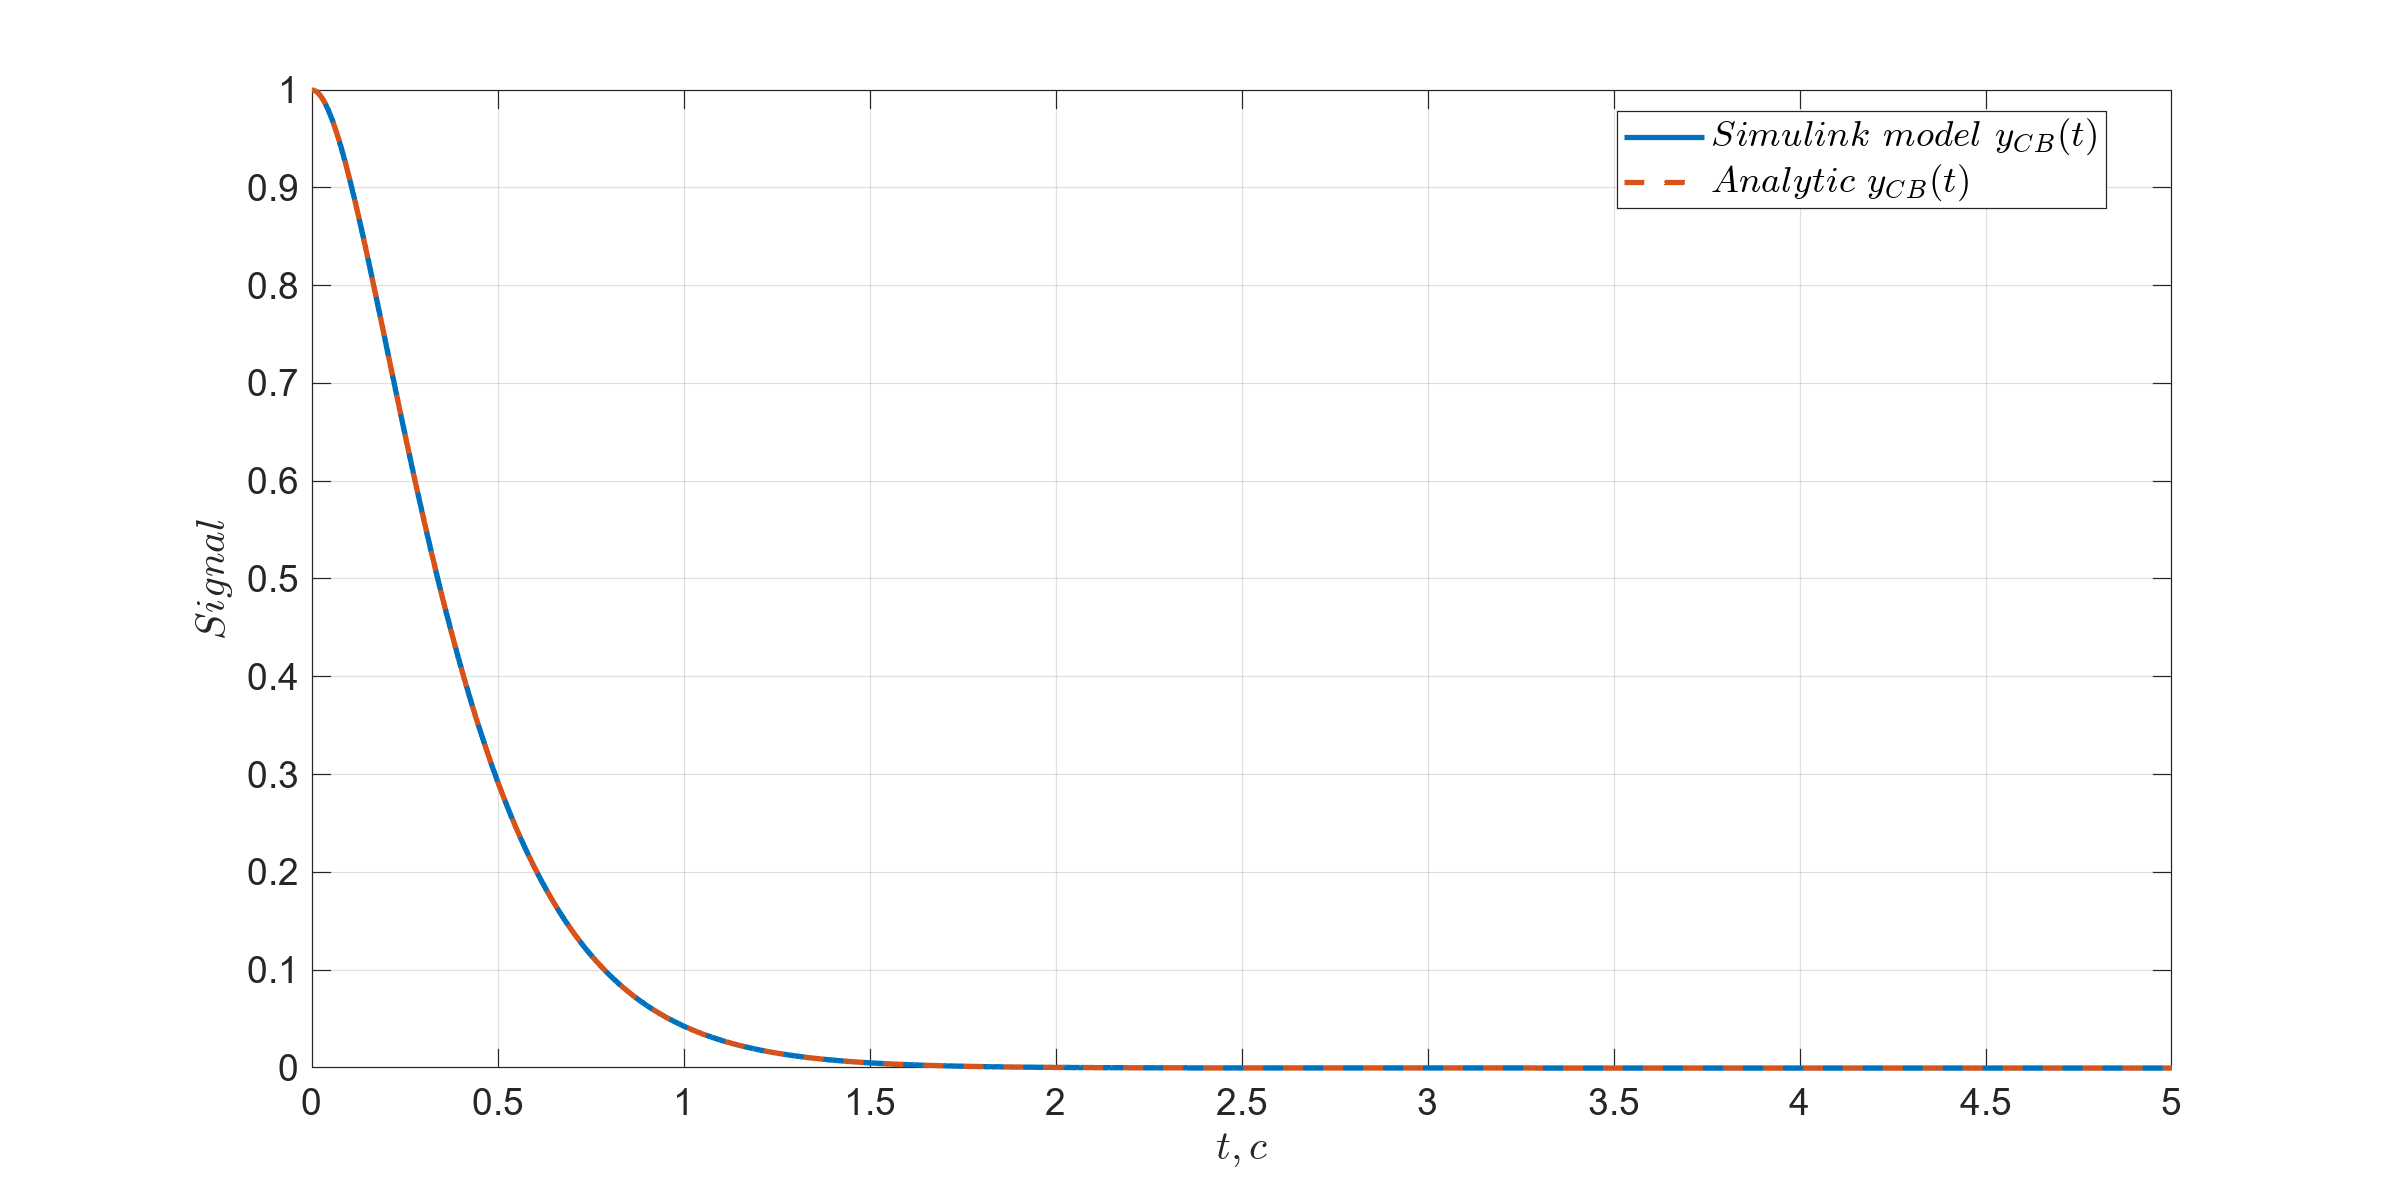

y_fm_array = {@y_fm_1, @y_fm_2, @y_fm_3, @y_fm_4, @y_fm_5, @y_fm_6};
simtime = 5;
time_interval = linspace(0, simtime, 10000);

for k=1:6
    y = y_fm_array{k}(time_interval);
    dot_y_0 = dot_y_0_arr(k);
    y_0 = y_0_arr(k);
    a_0 = a_0_arr(k);
    a_1 = a_1_arr(k);

    plot_1 = sim("lab_2_1.slx", simtime);
    plot(plot_1.y.Time, plot_1.y.Data, LineWidth=2, LineStyle="-");
    hold on;
    plot(time_interval, y, LineWidth=2, LineStyle="--");
    
    grid on;
    legend("$Simulink\ model\ y_{CB}(t)$", "$Analytic\ y_{CB}(t)$", Location="best", FontSize=14, Interpreter="latex");
    xlabel("$t, c$", Interpreter="latex");
    ylabel("$Signal$", Interpreter="latex");
    set(gcf, Position=[100, 100, 1200, 600]);   
    set(gca, FontSize=14);
    
    hold off;
    filename = sprintf('images/plot_1_%d.png', k);
    exportgraphics(gcf, filename, 'Resolution', 200);
end;

function y = y_fm_1(t)
    y = 5.5 .* exp(-4.5 .* t) - 4.5 .* exp(-5.5 .* t);
end
function y = y_fm_2(t)
    y = exp(-3.7 .* t) .*(0.74 .* sin(5 .* t) + cos(5 .* t));
end
function y = y_fm_3(t)
    y = cos(29 .* t);
end
function y = y_fm_4(t)
    y = exp(0.7 .* t) .* (-0.007 .* sin(5 .* t) + 0.05 .* cos(5 .* t));
end
function y = y_fm_5(t)
    y = -0.225 .* exp(5.5 .* t) + 0.275 .* exp(4.5 .* t);
end
function y = y_fm_6(t)
    y = 1 ./ 56 .* exp(2.8 .* t) - 1 ./ 56 .* exp(-2.8 .* t);
end